## SHALLOW LEARNING

#### Playing with MATLAB's FITRNET Function

Inbuilt function to train a regression neural net

This appears to just be an ANN

rng("default")

N = 15000; %datapoints
m = 10; %num input features
input_data = [rand(N,m)] %input data normalised to btwn 0 and 1

input_data =     0.8147    0.2858    0.8252    0.1839    0.6388    0.3175    0.8937    0.2068    0.0886    0.3919
    0.9058    0.9312    0.0908    0.0488    0.2237    0.6382    0.8162    0.4302    0.4828    0.6212
    0.1270    0.7999    0.2064    0.5280    0.1693    0.2119    0.9474    0.9661    0.9015    0.4001
    0.9134    0.3311    0.7932    0.6577    0.3909    0.4541    0.2403    0.8127    0.5778    0.4569
    0.6324    0.7374    0.6817    0.3300    0.4590    0.5029    0.5797    0.6967    0.9693    0.3711
    0.0975    0.5674    0.4700    0.1683    0.8454    0.7209    0.1888    0.1507    0.4572    0.4465
    0.2785    0.0161    0.8978    0.1655    0.5333    0.5400    0.3513    0.8656    0.8015    0.2468
    0.5469    0.4255    0.4085    0.0459    0.0713    0.1541    0.6063    0.7257    0.3339    0.0212
    0.9575    0.0294    0.6585    0.2291    0.3536    0.1219    0.6446    0.5820    0.1271    0.1138
    0.9649    0.7842    0.9584    0.5768    0.9280    0.5349    0.6153    0.12


powers = randi([1,6],[1,m])

powers =      5     3     5     1     5     1     6     2     5     6


coeffs = [randn(m,1)]

coeffs =     0.6616
   -0.1329
    1.6312
    1.6487
   -0.2863
    0.6266
    0.8173
   -0.9155
    0.0620
    1.6330


const = rand(1)

const = 0.2846

actual_model = @(X) X*coeffs+const + 0.2.*sin(X*coeffs);

[output_data, shift, scale] = normalize(actual_model(input_data))

output_data =     0.4975
   -0.4860
   -1.0178
    0.4903
   -0.1764
   -0.8510
   -0.8117
   -2.0834
   -0.6044
    2.5352


shift = 3.1847

scale = 0.8260


partition_variable = cvpartition(N, "Holdout",0.3);
trainingIndices = training(partition_variable);
trainInput = input_data(trainingIndices,:);
trainOutput = output_data(trainingIndices,:);

testIndices = test(partition_variable);
testInput = input_data(testIndices,:);
testOutput = output_data(testIndices,:);


allModels = {};
i = 1;
lambda = [1e-8,1e-7, 1e-6,1e-5, 2e-5, 1e-4, 2e-4, 5e-4, 1e-3, 2e-3, 5e-3, 0.01, 0.02, 0.04, 0.08, 0.16, 0.32, 0.64, 1.28];

for L = drange(lambda)
    allModels(i) = {fitrnet(trainInput, trainOutput, 'Standardize', false, ...
    'LayerSizes', [5,5], 'Lambda', L)};
    i = i+1;
end

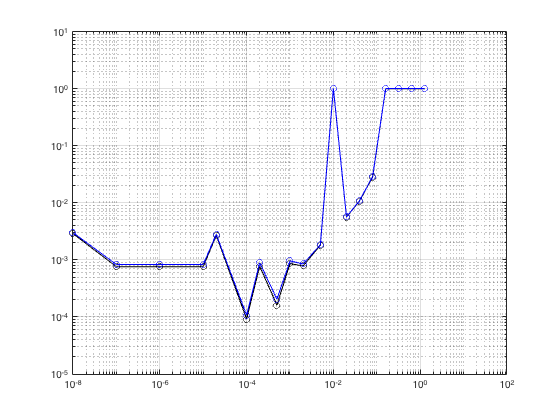


trainLoss = [];
testLoss = [];
for i=1:length(lambda)
    trainLoss(i) = loss(allModels{i}, trainInput, trainOutput);;
    testLoss(i) = loss(allModels{i}, testInput, testOutput);
end
clf
loglog(lambda, trainLoss, '-ok')
hold on
loglog(lambda, testLoss, '-ob')

grid on

InputCheck = rand([1,10])
fprintf('Actual -> %.4f', actual_model(InputCheck))
fprintf('Predicted -> %.4f', predict(allModels{3}, InputCheck)*scale+shift)


#### Playing with Patternnet

Same example as above

The perform function uses MSE but seems to be a lot higher than just calculating the MSE myself??

net = patternnet([5,5]);
% net.numInputs = m;
net.layers{1}.transferFcn = 'purelin';
net.layers{2}.transferFcn = 'purelin';
net.layers{3}.transferFcn = 'purelin';
% net.performParam.regularization = 1e-4;
net.performFcn = 'mse';
% net.inputConnect = [ones(1,m); zeros(2,m)];
% net.trainFcn = 'trainbfg';
% view(net)
% trainInputCell = mat2cell(trainInput', [ones(1,m)], [length(trainInput)]);
% trainOutputCell = mat2cell(trainOutput', [ones(1,1)], [length(trainOutput)]);
% 
% testInputCell = mat2cell(testInput', [ones(1,m)], [length(testInput)]);
% testOutputCell = mat2cell(testOutput', [ones(1,1)], [length(testOutput)]);

% net = train(net, trainInput', trainOutput')
% perform(net, testInput', testOutput')


mse_history = [];
training_data_sizes = floor(logspace(0,4,12));
for i=training_data_sizes
    tempnet = net; %must reset net between iterations
%     trainInputCell = mat2cell(trainInput(1:i,:)', [ones(1,m)], [i]);
%     trainOutputCell = mat2cell(trainOutput(1:i,:)', [ones(1,1)], [i]);

    tempnet = train(tempnet, trainInput(1:i,:)', trainOutput(1:i,:)');
%     [i, perform(tempnet, trainInput, trainOutput), perform(tempnet, testInput, testOutput)]
    mse_history = [mse_history; mean((trainOutput' - tempnet(trainInput')).^2), mean((testOutput' - tempnet(testInput')).^2)];
end
net = tempnet;

clf
loglog(training_data_sizes, mse_history(:,1))
hold on
loglog(training_data_sizes, mse_history(:,2))
grid on
xlabel("Size of Dataset")
ylabel("MSE")

InputCheck = rand([10,1]);
fprintf('Actual -> %.4f', actual_model(InputCheck'))
fprintf('Predicted -> %.4f', tempnet(InputCheck)*scale+shift)

play_in = 0:0.05:1;
clf
plot(play_in, actual_model([play_in', zeros(length(play_in),m-1)]))
hold on
plot(play_in, net([play_in', zeros(length(play_in),m-1)]'))
grid on


#### Random Forest

Was used by Q. Xie in "Machine Learning Methods for Real-Time Blood Pressure Measurement Based on Photoplethysmography". There is a high level Matlab way to implement but requires reading up about the technique a bit and considering properties properly

#### LSTM 

Was used by L. Harfiya in "Continuous Blood Pressure Estimation Using Exclusively Photopletysmography by LSTM-Based Signal-to-Signal Translation". There is a high level Matlab way to implement but requires reading up about the technique a bit and considering properties properly

#### Support Vector Machine Regression

https://towardsdatascience.com/unlocking-the-true-power-of-support-vector-regression-847fd123a4a0

rsvmModel = fitrsvm(trainInput, trainOutput);

frpintf("Converged? %i", rsvmModel.ConvergenceInfo.Converged)

rsvmModel

i = randi(length(testInput));
fprintf("Actual Model -> %.4f", actual_model(testInput(i,:)))
fprintf("Predicted Model -> %.4f", predict(rsvmModel, testInput(i,:)).*scale+shift)



### Playing With Actual Data

%for feature files if the files are too big, tall arrays may be needed
[inputdata, outputdata, normFactors] = MLFeatureRead();

Removed 0 rows from datainput features has 13725 rows and 612 columns 
output features has 13725 rows and 605 columns 


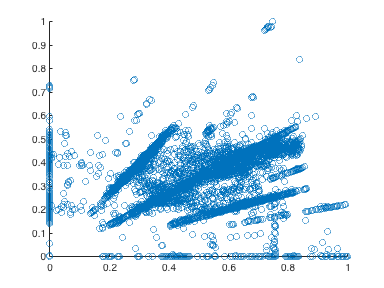


partition_variable = cvpartition(height(inputdata), "Holdout",0.25);
trainingIndices = training(partition_variable);
trainInput = inputdata(trainingIndices,:);
trainOutput = outputdata(trainingIndices,:);

testIndices = test(partition_variable);
testInput = inputdata(testIndices,:);
testOutput = outputdata(testIndices,:);

clf
scatter(inputdata.PPGBW, outputdata.ABPBW)

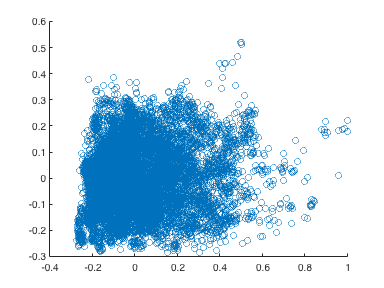

% xtitle("PPG Bandwidth(norm)")
% ytitle("ABP Bandwidth(norm)")

clf
scatter(inputdata.CT, outputdata.MAP)

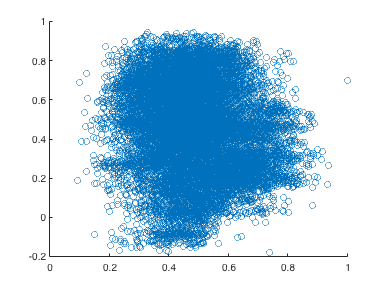


clf
scatter(inputdata.RespRate, outputdata.MeanSBP)

rsvmmodel = fitrsvm(trainInput, trainOutput.MAP, 'KernelFunction', 'linear','KernelScale', 1);

actualMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedMAP = predict(rsvmmodel, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingError = (predictedMAP-actualMAP)./actualMAP;
% testingError = testingError(find(~isnan(testingError)));

actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTrainMAP = predict(rsvmmodel, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
trainingError = (predictedTrainMAP-actualTrainMAP)./actualTrainMAP;
% trainingError = trainingError(find(~isnan(trainingError)));

fprintf("Average MAP test error: %.2f%%", mean(abs(testingError(find(~isnan(testingError))))).*100)

Average MAP test error: 9.32%

fprintf("Average MAP train error: %.2f%%", mean(abs(trainingError(find(~isnan(trainingError))))).*100)

Average MAP train error: 9.16%

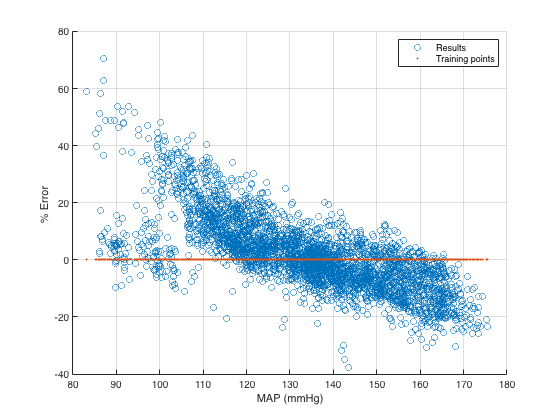


clf
scatter(actualMAP, testingError.*100);
hold on
scatter(actualMAP, 0.*actualMAP, '.')
xlabel("MAP (mmHg)")
ylabel("% Error ")
grid on
legend("Results", "Training points")

rng default
rsvmmodel_opt = fitrsvm(trainInput, trainOutput.MAP, 'OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
    'expected-improvement-plus', 'UseParallel', true));

Copying objective function to workers...
Done copying objective function to workers.
|==============================================================================================================================|
| Iter | Active  | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |      Epsilon |
|      | workers | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              |              |
|==============================================================================================================================|
|    1 |       3 | Best   |    0.015215 |      6.6696 |    0.015215 |    0.015215 |       27.209 |     0.011201 |       2.7307 |
|    2 |       3 | Accept |    0.015215 |      6.9131 |    0.015215 |    0.015215 |     0.011062 |       545.55 |       7.2124 |
|    3 |       4 | Accept |    0.015215 |      3.7663 |    0.015215 |    0.015215 |       16.258 |     0.011103 |        11.56 |
|    4 |    


actualMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedMAP = predict(rsvmmodel_opt, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingError = (predictedMAP-actualMAP)./actualMAP;

actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTrainMAP = predict(rsvmmodel_opt, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
trainingError = (predictedTrainMAP-actualTrainMAP)./actualTrainMAP;


clf
scatter(actualMAP, testingError.*100);
xlabel("MAP (mmHg)")
ylabel("% Error ")
grid on

fprintf("Average MAP test error: %.2f%%", mean(abs(testingError)).*100)
fprintf("Average MAP train error: %.2f%%", mean(abs(trainingError)).*100)

#### ANN

[5,5]

rnetModels2_5={};
dataSizes = floor(logspace(0, log10(height(trainInput)),20 ));
trainingError=[];
testingError=[];


for idx=1:length(dataSizes)
    N = dataSizes(idx);
    rnetModels2_5{idx} = fitrnet(trainInput(1:N,:), trainOutput.MAP(1:N), 'Standardize', false, ...
        'LayerSizes', [5,5], 'Lambda', 0);

    actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTestMAP = predict(rnetModels2_5{idx}, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    testingError(idx) = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP);

    actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTrainMAP = predict(rnetModels2_5{idx}, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    trainingError(idx) = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP);
end

clf
semilogx(dataSizes, trainingError.*100, 'o-')
hold on
semilogx(dataSizes, testingError.*100, '*-')
legend("Train", "Test")
ylim([0,45])
title("[5,5]")
xlabel("Training Set Size")
ylabel("Mean Absolute Error (%)")
grid on

clf
% scatter(actualTestMAP, actualTestMAP, '.')
hold on
scatter(actualTestMAP, (predictedTestMAP-actualTestMAP)./actualTestMAP.*100 )
xlabel("MAP (mmHg)")
ylabel("MAE (%)")
grid on

% fprintf("-- rANN --")
% fprintf("Average MAP train error: %.2f%%", mean(abs(trainingError)).*100)
% fprintf("Average MAP test error: %.2f%%", mean(abs(testingError)).*100)


rnetModels2_5a = fitrnet(trainInput, trainOutput.MAP, 'Standardize', false, ...
    'LayerSizes', [5,5], 'Lambda', 0);


actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestMAP = predict(rnetModels2_5a, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
% notNanIdx = find(~isnan(predictedTestMAP));
% predictedTestMAP  = predictedTestMAP(notNanIdx);
% actualTestMAP = actualTestMAP(notNanIdx);
testingError = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP)

testingError = 0.0746

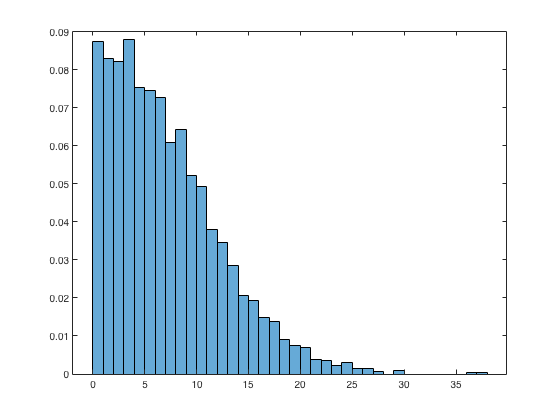

clf
histogram(abs(actualTestMAP-predictedTestMAP), 'Normalization', 'probability')


actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTrainMAP = predict(rnetModels2_5a, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
% notNanIdx = find(~isnan(predictedTrainMAP));
% predictedTrainMAP  = predictedTrainMAP(notNanIdx);
% actualTrainMAP = actualTrainMAP(notNanIdx);
trainingError = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP)

trainingError = 0.0732


fprintf("Average MAP train error: %.2f%%", mean(abs(trainingError)).*100)

Average MAP train error: 7.32%

fprintf("Average MAP test error: %.2f%%", mean(abs(testingError)).*100)

Average MAP test error: 7.46%

fprintf("Probs of error less than 10 mmHg: %2.2f%%", 100*sum(abs(actualTestMAP-predictedTestMAP)<10)./length(actualTestMAP))

Probs of error less than 10 mmHg: 74.00%

fprintf("μ ± SD: %3.2f ± %3.2f mmHg ", mean(abs(actualTestMAP-predictedTestMAP)), std(abs(actualTestMAP-predictedTestMAP)) )

μ ± SD: 7.13 ± 5.31 mmHg 

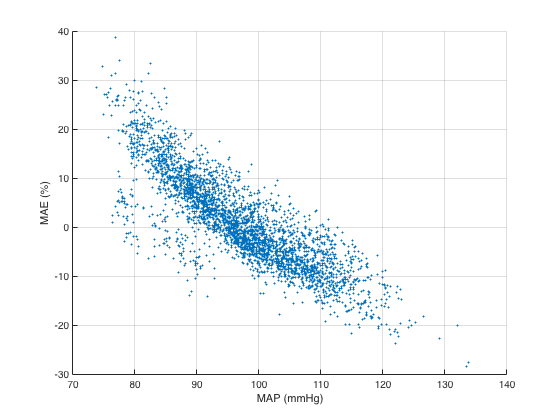



clf
% scatter(actualTestMAP, actualTestMAP, '.')
hold on
scatter(actualTestMAP, (predictedTestMAP-actualTestMAP)./actualTestMAP.*100,'.' )
xlabel("MAP (mmHg)")
ylabel("MAE (%)")
grid on

[50,50, 50, 50]

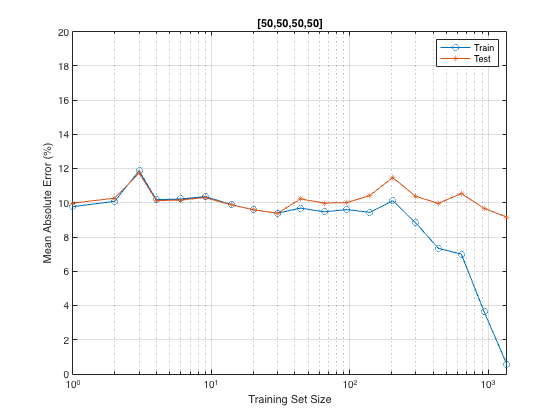

rnetModels4_50={};
dataSizes = floor(logspace(0, log10(height(trainInput)),20 ));
L = floor(logspace(-3, log10(2), 20));
trainingError=[];
testingError=[];


for idx=1:length(dataSizes)
    N = dataSizes(idx);
    rnetModels4_50{idx} = fitrnet(trainInput(1:N,:), trainOutput.MAP(1:N), 'Standardize', false, ...
        'LayerSizes', [50,50,50,50], 'Lambda', 0.001);
    
    actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTestMAP = predict(rnetModels4_50{idx}, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    testingError(idx) = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP);
    
    actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTrainMAP = predict(rnetModels4_50{idx}, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    trainingError(idx) = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP);
end
clf
semilogx(dataSizes, trainingError.*100, 'o-')
hold on
semilogx(dataSizes, testingError.*100, '*-')
legend("Train", "Test")
title("[50,50,50,50]")
ylim([0,20])
xlabel("Training Set Size")
ylabel("Mean Absolute Error (%)")
grid on

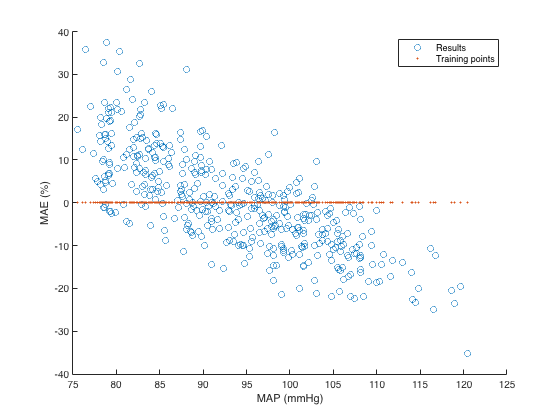




tErr = predict(rnetModels4_50{20}, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
clf
scatter(actualTestMAP, (tErr-actualTestMAP)./actualTestMAP.*100)
hold on
scatter(actualTestMAP, 0.*actualTestMAP, '.')
xlabel("MAP (mmHg)")
ylabel("MAE (%)")
legend("Results", "Training points")

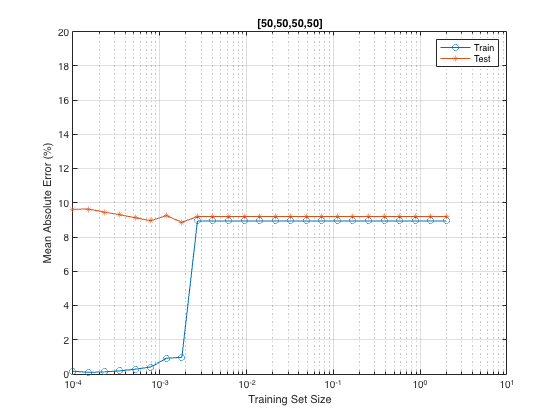

rnetModels4_50={};
L = logspace(-4, log10(2), 25);
trainingError=[];
testingError=[];

for idx=1:length(L)
    rnetModels4_50{idx} = fitrnet(trainInput, trainOutput.MAP, 'Standardize', false, ...
        'LayerSizes', [50,50,50,50], 'Lambda', L(idx));
    
    actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTestMAP = predict(rnetModels4_50{idx}, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    testingError(idx) = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP);
    
    actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTrainMAP = predict(rnetModels4_50{idx}, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    trainingError(idx) = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP);
end
clf
semilogx(L, trainingError.*100, 'o-')
hold on
semilogx(L, testingError.*100, '*-')
legend("Train", "Test")
title("[50,50,50,50]")
ylim([0,20])
xlabel("Training Set Size")
ylabel("Mean Absolute Error (%)")
grid on

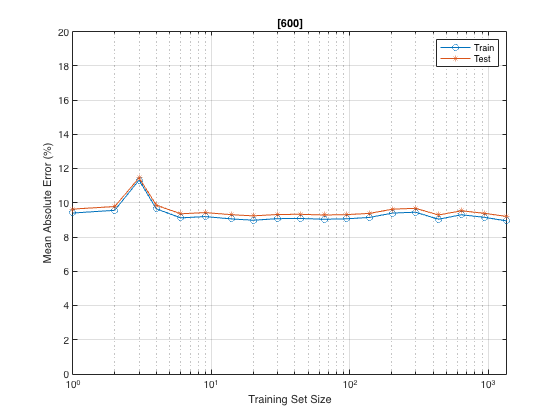

rnetModels1_600={};
dataSizes = floor(logspace(0, log10(height(trainInput)),5 ));
trainingError=[];
testingError=[];


for idx=1:length(dataSizes)
    N = dataSizes(idx);
    rnetModels1_600{idx} = fitrnet(trainInput(1:N,:), trainOutput.MAP(1:N), 'Standardize', false, ...
        'LayerSizes', [600], 'Lambda', 1);

    actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTestMAP = predict(rnetModels1_600{idx}, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    testingError(idx) = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP);

    actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTrainMAP = predict(rnetModels1_600{idx}, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    trainingError(idx) = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP);
end

clf
semilogx(dataSizes, trainingError.*100, 'o-')
hold on
semilogx(dataSizes, testingError.*100, '*-')
legend("Train", "Test")
title("[600]")
ylim([0,20])
xlabel("Training Set Size")
ylabel("Mean Absolute Error (%)")
grid on

% pool = parpool
rnetModels1_600a = fitrnet(trainInput, trainOutput.MAP, 'Standardize', true, ...
     'LayerSizes', [600], 'Lambda', 1e-3, 'Verbose',1, 'VerboseFrequency', 5)

Unrecognized function or variable 'trainInputT'.

actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestMAP = predict(rnetModels1_600a, testInput,'useParallel','yes')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingError = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP)

actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTrainMAP = predict(rnetModels1_600a, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
trainingError = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP)

fprintf("Average MAP train error: %.2f%%", mean(abs(trainingError)).*100)
fprintf("Average MAP test error: %.2f%%", mean(abs(testingError)).*100)
fprintf("Probs of error less than 10 mmHg: %2.2f%%", 100*sum(abs(actualTestMAP-predictedTestMAP)<10)./length(actualTestMAP))
fprintf("μ ± SD: %3.2f ± %3.2f mmHg ", mean(abs(actualTestMAP-predictedTestMAP)), std(abs(actualTestMAP-predictedTestMAP)) )


clf
% scatter(actualTestMAP, actualTestMAP, '.')
hold on
scatter(actualTestMAP, (predictedTestMAP-actualTestMAP)./actualTestMAP.*100,'.' )
xlabel("MAP (mmHg)")
ylabel("MAE (%)")
grid on

rnetModels1_600={};
L = logspace(-4, log10(2), 5);
trainingError=[];
testingError=[];

parfor idx=1:length(L)
    fprintf("iter %i",idx)
    rnetModels1_600{idx} = fitrnet(trainInput, trainOutput.MAP, 'Standardize', false, ...
        'LayerSizes', [600], 'Lambda', L(idx));
    
    actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTestMAP = predict(rnetModels1_600{idx}, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    testingError(idx) = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP);
    
    actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTrainMAP = predict(rnetModels1_600{idx}, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    trainingError(idx) = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP);
end

iter 1iter 5iter 2iter 3iter 4

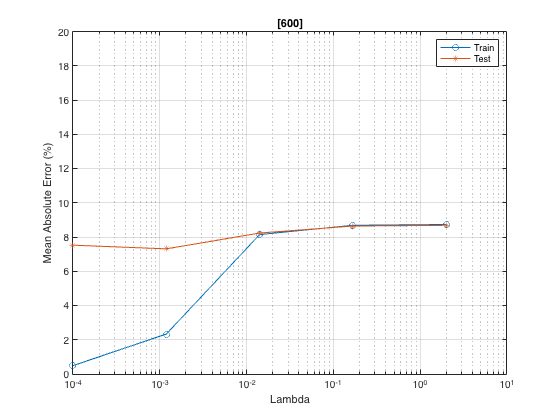

clf
semilogx(L, trainingError.*100, 'o-')
hold on
semilogx(L, testingError.*100, '*-')
legend("Train", "Test")
title("[600]")
ylim([0,20])
xlabel("Lambda")
ylabel("Mean Absolute Error (%)")
grid on

rnetModels3_600={};
L = logspace(-4, log10(2), 25);
trainingError=[];
testingError=[];

for idx=1:length(L)
    idx
    rnetModels3_600{idx} = fitrnet(trainInput, trainOutput.MAP, 'Standardize', false, ...
        'LayerSizes', [600,600,600], 'Lambda', L(idx));
    
    actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTestMAP = predict(rnetModels3_600{idx}, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    testingError(idx) = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP);
    
    actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTrainMAP = predict(rnetModels3_600{idx}, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    trainingError(idx) = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP);
end

idx = 1

idx = 2

idx = 3

clf
semilogx(L, trainingError.*100, 'o-')
hold on
semilogx(L, testingError.*100, '*-')
legend("Train", "Test")
title("[600,600,600]")
ylim([0,20])
xlabel("Training Set Size")
ylabel("Mean Absolute Error (%)")
grid on


rnetModels3_600a = fitrnet(trainInput, trainOutput.MAP, 'Standardize', false, ...
    'LayerSizes', [600,600,600], 'Lambda', 1e-3);

actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestMAP = predict(rnetModels3_600a, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingError = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP);

actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTrainMAP = predict(rnetModels3_600a, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
trainingError = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP);

fprintf("Average MAP train error: %.2f%%", mean(abs(trainingError)).*100)

Average MAP train error: 4.95%

fprintf("Average MAP test error: %.2f%%", mean(abs(testingError)).*100)

Average MAP test error: 7.85%

fprintf("Probs of error less than 10 mmHg: %2.2f%%", 100*sum(abs(actualTestMAP-predictedTestMAP)<10)./length(actualTestMAP))

Probs of error less than 10 mmHg: 71.58%

fprintf("μ ± SD: %3.2f ± %3.2f mmHg ", mean(abs(actualTestMAP-predictedTestMAP)), std(abs(actualTestMAP-predictedTestMAP)) )

μ ± SD: 7.54 ± 5.75 mmHg 

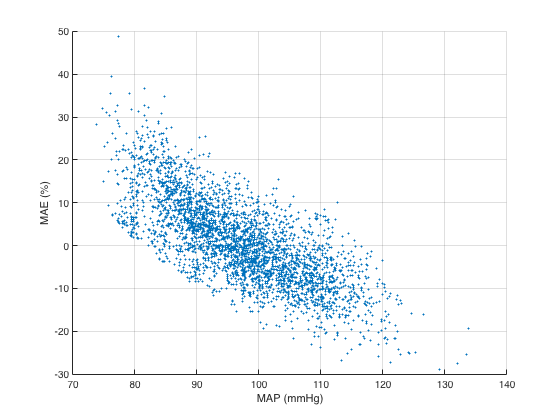


clf
% scatter(actualTestMAP, actualTestMAP, '.')
hold on
scatter(actualTestMAP, (predictedTestMAP-actualTestMAP)./actualTestMAP.*100,'.' )
xlabel("MAP (mmHg)")
ylabel("MAE (%)")
grid on

numFeatures = width(trainInput);

% trainInputLSTM = {};
% trainOutputLSTM = {};
% for i = 1:height(trainInput)
%     trainInputLSTM(i) = table2cell(trainInput(i,:));
%     trainOutputLSTM(i) = {trainOutput.MAP};
% end
% 
% testInputLSTM = {};
% testOutputLSTM = {};
% for i = 1:height(testInput)
%     testInputLSTM(i) = table2cell(testInput(i,:));
%     testOutputLSTM(i) = {testOutput.MAP};
% end


layers = [...
    sequenceInputLayer(numFeatures)
    batchNormalizationLayer
    bilstmLayer(128, 'OutputMode', 'sequence')
    batchNormalizationLayer
    lstmLayer(128, 'OutputMode', 'sequence')
    batchNormalizationLayer
    lstmLayer(128, 'OutputMode', 'sequence')
    batchNormalizationLayer
    fullyConnectedLayer(1)
    regressionLayer]

layers =   10×1 Layer array with layers:

     1   ''   Sequence Input        Sequence input with 612 dimensions
     2   ''   Batch Normalization   Batch normalization
     3   ''   BiLSTM                BiLSTM with 128 hidden units
     4   ''   Batch Normalization   Batch normalization
     5   ''   LSTM                  LSTM with 128 hidden units
     6   ''   Batch Normalization   Batch normalization
     7   ''   LSTM                  LSTM with 128 hidden units
     8   ''   Batch Normalization   Batch normalization
     9   ''   Fully Connected       1 fully connected layer
    10   ''   Regression Output     mean-squared-error


%**should change test data to validation data
%loss function should be huber https://www.mathworks.com/help/deeplearning/ug/define-custom-regression-output-layer.html

% a = table2cell(trainInput);
% b = {};
% for i=1:height(trainOutput)
%     b(i) = {trainOutput.MAP};
% end
inputTrainLSTM = table2array(trainInput);
inputTrainLSTM  = reshape(inputTrainLSTM, [], height(trainInput));
outputTrainLSTM = [trainOutput.MAP]';
inputTestLSTM = table2array(testInput);
inputTestLSTM  = reshape(inputTestLSTM, [], height(testInput));
outputTestLSTM = [testOutput.MAP]';

options = trainingOptions('sgdm',...
    'MiniBatchSize', 32,...
    'InitialLearnRate', 0.001, ...
    'OutputNetwork', 'best-validation-loss', ...
    'ValidationData', {inputTestLSTM, outputTestLSTM}, ...
    'ExecutionEnvironment', 'cpu',...
    'MaxEpochs', 20,...
    'ValidationFrequency', 10,...
    'VerboseFrequency', 10)

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 20
                   MiniBatchSize: 32
                         Verbose: 1
                VerboseFrequency: 10
                  ValidationData: {[612×3431 double]  [0.0057 -0.1217 -0.0609 0.0297 -0.0649 -0.0125 -0.1734 -0.1717 0.0768 0.0683 -0.0180 -0.0968 -0.1431 -0.0437 -0.1355 -0.1480 -0.0636 0.0730 -0.0932 -0.0869 -0.0467 0.0246 0.0658 0.0950 0.1162 … ]}
             ValidationFrequency: 10
             


[netLSTM, info] = trainNetwork(inputTrainLSTM,outputTrainLSTM, layers, options)

|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:27 |         1.68 |         3.23 |       1.4126 |       5.2202 |          0.0010 |


a = predict(netLSTM,inputTestLSTM).*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');  
b = outputTestLSTM.*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');

mean(abs(a-b))

ans = single
13.3325

options = trainingOptions('rmsprop',...
    'MiniBatchSize', 32,...
    'InitialLearnRate', 0.001, ...
    'ValidationData', {inputTestLSTM, outputTestLSTM}, ...
    'ExecutionEnvironment', 'gpu',...
    'MaxEpochs', 150,...
    'ValidationFrequency', 10,...
    'VerboseFrequency', 10)

#### LSTM

[https://www.mathworks.com/help/deeplearning/ug/long-short-term-memory-networks.html](https://www.mathworks.com/help/deeplearning/ug/long-short-term-memory-networks.html)

see sequence to sequence regression

[https://www.mathworks.com/help/deeplearning/ug/sequence-to-sequence-regression-using-deep-learning.html](https://www.mathworks.com/help/deeplearning/ug/sequence-to-sequence-regression-using-deep-learning.html)

addSubPaths();
opts = readOptionsStruct();
fileList = dir(opts.segmented_file_dir+"*.txt");
numFiles = length(fileList);

inputFeats = [];
outputFeats = [];

interp_pts = 0:0.01:18;

for idx=1:numFiles
    fprintf("\b\b\b\b\b\b%6i", idx);

    dataFile = fopen(opts.segmented_file_dir + fileList(idx).name);
    if(dataFile == -1)
        inputFeatures = [];
        fprintf("%s not found. Returning from function.", opts.segmented_file_dir+segmentName)
        return; 
    end
    data = cell2mat(textscan( dataFile, ...
    '%f %f %f', 'TreatAsEmpty', '-', 'EmptyValue', 0));
    fclose(dataFile);

    time = data(:,1);
    abp_wave = data(:,2);
    ppg_wave = data(:,3);

    interp_ppg = interp1(time, ppg_wave, interp_pts);
    interp_abp = interp1(time, abp_wave, interp_pts);
    [f, PPG_fft] = singlesidedFFT(interp_pts, interp_ppg);
    stopIdx = find(f >= 20,1);
    [~, ABP_fft] = singlesidedFFT(interp_pts, interp_abp);
    
    inputFeats(idx, :) = [abs(PPG_fft(1:stopIdx)), angle(PPG_fft(1:stopIdx))];
    outputFeats(idx,:) = [abs(ABP_fft(1:stopIdx)), angle(ABP_fft(1:stopIdx))];

end

  1818

partition_variable = cvpartition(height(inputFeats), "Holdout",0.25);
trainingIndices = training(partition_variable);
trainInputF = inputFeats(trainingIndices,:);
trainOutputF = outputFeats(trainingIndices,:);

testIndices = test(partition_variable);
testInputF = inputFeats(testIndices,:);
testOutputF = outputFeats(testIndices,:); 


numFeatures = width(trainInputF);
numResponses = width(trainOutputF);
numHiddenUnits = 200;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits,'OutputMode','sequence')
    fullyConnectedLayer(50)
    dropoutLayer(0.1)
    fullyConnectedLayer(numResponses)
    regressionLayer];

maxEpochs = 60;
miniBatchSize = 20;

options = trainingOptions('adam', ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'InitialLearnRate',0.01, ...
    'GradientThreshold',1, ...
    'Shuffle','never', ...
    'Plots','training-progress',...
    'Verbose',0);

net = trainNetwork(trainInputF',trainOutputF',layers,options);


YPred = predict(net,testInputF(200,:)','MiniBatchSize',1)
actFFT = testOutputF(200,1:362).*exp(i.*testOutputF(200,363:end));
PredFFT = YPred(1:362).*exp(i.*YPred(363:end));
deltaf = 1/(0.01.*1801);
[pred_time, pred_abp] = singlesidedIFFT([0:deltaf:20+deltaf], PredFFT);
[act_time, act_abp] = singlesidedIFFT([0:deltaf:20+deltaf], actFFT);

clf
plot(pred_time, pred_abp)
hold on
plot(act_time, act_abp)


Following LSTM from Paviglianiti et al. [https://link.springer.com/content/pdf/10.1007/s12559-021-09910-0.pdf](https://link.springer.com/content/pdf/10.1007/s12559-021-09910-0.pdf) 

addSubPaths();
opts = readOptionsStruct();
load('NormalisationFactors.mat')
fileList = dir(opts.segmented_file_dir+"*.txt");
numFiles = length(fileList);

inputFeats = zeros(5000,1250);
outputFeats = zeros(5000,1250);

segLength = 10;
segOverlap = 0.2; %proportion that the interpolated points are allowed to overlap in the same segment 

numIndices = 0;
for idx=1:numFiles
    fprintf("\b\b\b\b\b\b%6i", idx);

    dataFile = fopen(opts.segmented_file_dir + fileList(idx).name);
    if(dataFile == -1)
        inputFeatures = [];
        fprintf("%s not found. Returning from function.", opts.segmented_file_dir+segmentName)
        continue; 
    end
    data = cell2mat(textscan( dataFile, ...
    '%f %f %f', 'TreatAsEmpty', '-', 'EmptyValue', 0));
    fclose(dataFile);

    time = data(:,1);
    abp_wave = data(:,2);
    ppg_wave = data(:,3);

    numAvailableSegs = floor(time(end)/segLength*(1+segOverlap));
    
    for i = 1:numAvailableSegs
        numIndices = numIndices+1;
        startInterp = 10*(i-1)*(1-segOverlap);
        if(i == 1); startInterp = 0; end;
        endInterp = startInterp +10;
        interp_pts = linspace(startInterp,endInterp,1250);

        interp_ppg = interp1(time, ppg_wave, interp_pts);
        interp_ppg = (interp_ppg-normFactors('PPGAmpMean'))./normFactors('PPGAmpScale');
        interp_abp = interp1(time, abp_wave, interp_pts);
        interp_abp = (interp_abp-normFactors('ABPAmpMean'))./normFactors('ABPAmpScale');
        
        if(~isempty(find(isnan(interp_ppg))) && ~isempty(find(isnan(interp_abp)))); continue; end;
        inputFeats(numIndices, :) = interp_ppg;
        outputFeats(numIndices, :) = interp_abp;
    end

end

  1818

 
% load('inputFeatsTime.mat')
% load('outputFeatsTime.mat')

partition_variable = cvpartition(height(inputFeats), "Holdout",0.25);
trainingIndices = training(partition_variable);
trainInputT = inputFeats(trainingIndices,:);
trainOutputT = outputFeats(trainingIndices,:);

testIndices = test(partition_variable);
testInputT = inputFeats(testIndices,:);
testOutputT = outputFeats(testIndices,:);


%try batches and batch normalisation next
layers = [...
    sequenceInputLayer(1250)
    bilstmLayer(128, 'OutputMode', 'sequence')
    batchNormalizationLayer
    lstmLayer(128, 'OutputMode', 'sequence')
    batchNormalizationLayer
    lstmLayer(128, 'OutputMode', 'sequence')
    batchNormalizationLayer
    fullyConnectedLayer(1250)
    regressionLayer]

layers =   9×1 Layer array with layers:

     1   ''   Sequence Input        Sequence input with 1250 dimensions
     2   ''   BiLSTM                BiLSTM with 128 hidden units
     3   ''   Batch Normalization   Batch normalization
     4   ''   LSTM                  LSTM with 128 hidden units
     5   ''   Batch Normalization   Batch normalization
     6   ''   LSTM                  LSTM with 128 hidden units
     7   ''   Batch Normalization   Batch normalization
     8   ''   Fully Connected       1250 fully connected layer
     9   ''   Regression Output     mean-squared-error


options = trainingOptions('adam',...
    'MiniBatchSize', 32,...
    'InitialLearnRate', 0.001, ...
    'OutputNetwork', 'best-validation-loss', ...
    'ValidationData', {testInputT', testOutputT'}, ...
    'ExecutionEnvironment', 'cpu',...
    'MaxEpochs', 80,...
    'ValidationFrequency', 10,...
    'VerboseFrequency', 10)

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 80
                   MiniBatchSize: 32
                         Verbose: 1
                VerboseFrequency: 10
                  ValidationData: {[1250×1672 double]  [1250×1672 double]}
             ValidationFrequency: 10
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
            ExecutionEnvironment: 'cpu'
                      WorkerLoad:

%**should change test data to validation data
%loss function should be huber https://www.mathworks.com/help/deeplearning/ug/define-custom-regression-output-layer.html


[netLSTM, info] = trainNetwork(trainInputT', trainOutputT', layers, options)

|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:20 |        17.75 |        17.19 |     157.4815 |     147.7888 |          0.0010 |
|      10 |          10 |       00:03:00 |        10.59 |        10.56 |      56.1050 |      55.7622 |          0.0010 |


%train from prev iteration
% [netLSTM, info] = trainNetwork(trainInputT', trainOutputT', netLSTM.Layers, options)


addSubPaths();
opts = readOptionsStruct();
load('NormalisationFactors.mat')
fileList = dir(opts.segmented_file_dir+"*.txt");
numFiles = length(fileList);

inputFeats = zeros(5000,1250);
outputFeats = zeros(5000,3);

segLength = 10;
segOverlap = 0.2; %proportion that the interpolated points are allowed to overlap in the same segment 

numIndices = 0;
for idx=1:numFiles
    fprintf("\b\b\b\b\b\b%6i", idx);

    dataFile = fopen(opts.segmented_file_dir + fileList(idx).name);
    if(dataFile == -1)
        inputFeatures = [];
        fprintf("%s not found. Returning from function.", opts.segmented_file_dir+segmentName)
        continue; 
    end
    data = cell2mat(textscan( dataFile, ...
    '%f %f %f', 'TreatAsEmpty', '-', 'EmptyValue', 0));
    fclose(dataFile);

    time = data(:,1);
    abp_wave = data(:,2);
    ppg_wave = data(:,3);

    numAvailableSegs = floor(time(end)/segLength*(1+segOverlap));
    
    for i = 1:numAvailableSegs
        numIndices = numIndices+1;
        startInterp = 10*(i-1)*(1-segOverlap);
        if(i == 1); startInterp = 0; end;
        endInterp = startInterp +10;
        interp_pts = linspace(startInterp,endInterp,1250);

        interp_ppg = interp1(time, ppg_wave, interp_pts);
        interp_ppg = (interp_ppg-normFactors('PPGAmpMean'))./normFactors('PPGAmpScale');
        interp_abp = interp1(time, abp_wave, interp_pts);
        interp_abp = (interp_abp-normFactors('ABPAmpMean'))./normFactors('ABPAmpScale');
        
        if(~isempty(find(isnan(interp_ppg))) && ~isempty(find(isnan(interp_abp)))); continue; end;
        inputFeats(numIndices, :) = interp_ppg;
        [~, ~, meanSBP, meanDBP, MAP] = findABPPeaks(interp_abp,125);
        outputFeats(numIndices,:) = [meanSBP, meanDBP, MAP];
    end

end

  1818

 
% load('inputFeatsTime.mat')
% load('outputFeatsTime.mat')

partition_variable = cvpartition(height(inputFeats), "Holdout",0.25);
trainingIndices = training(partition_variable);
trainInputT = inputFeats(trainingIndices,:);
trainOutputT = outputFeats(trainingIndices,:);

testIndices = test(partition_variable);
testInputT = inputFeats(testIndices,:);
testOutputT = outputFeats(testIndices,:);

% netRSVM = fitrsvm(trainInputT, trainOutputT(:,3), 'KernelFunction', 'linear',...
%     'KernelScale', 1);
netRSVM = fitrtree(trainInputT, trainOutputT(:,3),'MergeLeaves','off',...
    'MinParentSize',1,'Surrogate','on');

actualMAP = testOutputT(:,3)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedMAP = predict(netRSVM, testInputT)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingError = (predictedMAP-actualMAP)./actualMAP;
% testingError = testingError(find(~isnan(testingError)));

actualTrainMAP = trainOutputT(:,3)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTrainMAP = predict(netRSVM, trainInputT)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
trainingError = (predictedTrainMAP-actualTrainMAP)./actualTrainMAP;
% trainingError = trainingError(find(~isnan(trainingError)));

fprintf("Average MAP test error: %.2f%%", mean(abs(testingError(find(~isnan(testingError))))).*100)

Average MAP test error: 6.20%

fprintf("Average MAP train error: %.2f%%", mean(abs(trainingError(find(~isnan(trainingError))))).*100)

Average MAP train error: 0.15%


mean(abs(actualMAP-predictedMAP))

ans = 5.7729

%To run on GPU

addSubPaths();
opts = readOptionsStruct();
load('NormalisationFactors.mat')
fileList = dir(opts.segmented_file_dir+"*.txt");
numFiles = length(fileList);

inputFeats = zeros(40000,1250);
outputFeats = zeros(40000,1);

segLength = 10;
segOverlap = 0.2; %proportion that the interpolated points are allowed to overlap in the same segment 

numIndices = 0;
for idx=1:10000%numFiles
    fprintf("\b\b\b\b\b\b%6i", idx);

    dataFile = fopen(opts.segmented_file_dir + fileList(idx).name);
    if(dataFile == -1)
        inputFeatures = [];
        fprintf("%s not found. Returning from function.", opts.segmented_file_dir+segmentName)
        continue; 
    end
    data = cell2mat(textscan( dataFile, ...
    '%f %f %f', 'TreatAsEmpty', '-', 'EmptyValue', 0));
    fclose(dataFile);

    time = data(:,1);
    abp_wave = data(:,2);
    ppg_wave = data(:,3);

    numAvailableSegs = floor(time(end)/segLength*(1+segOverlap));

    
    for i = 1:numAvailableSegs
        numIndices = numIndices+1;
        startInterp = 10*(i-1)*(1-segOverlap);
        if(i == 1); startInterp = 0; end;
        endInterp = startInterp +10;
        interp_pts = linspace(startInterp,endInterp,1250);

        interp_ppg = interp1(time, ppg_wave, interp_pts);
        interp_ppg = (interp_ppg-normFactors('PPGAmpMean'))./normFactors('PPGAmpScale');
        interp_abp = interp1(time, abp_wave, interp_pts);
        interp_abp = (interp_abp-normFactors('ABPAmpMean'))./normFactors('ABPAmpScale');
        
        if(~isempty(find(isnan(interp_ppg))) && ~isempty(find(isnan(interp_abp)))); continue; end;
        inputFeats(numIndices, :) = interp_ppg;
        outputFeats(numIndices, 1) = mean(interp_abp);
    end

end

    24  DataQueue with properties:

    QueueLengt    25  DataQueue with properties:

    QueueLengt    26  DataQueue with properties:

    QueueLengt    27  DataQueue with properties:

    QueueLengt    28  DataQueue with properties:

    QueueLengt    29  DataQueue with properties:

    QueueLengt    30  DataQueue with properties:

    QueueLengt    31  DataQueue with properties:

    QueueLengt    32  DataQueue with properties:

    QueueLengt    33  DataQueue with properties:

    QueueLengt    34  DataQueue with properties:

    QueueLengt    35  DataQueue with properties:

    QueueLengt    36  DataQueue with properties:

    QueueLengt    37  DataQueue with properties:

    QueueLengt    38  DataQueue with properties:

    QueueLengt    39  DataQueue with properties:

    QueueLengt    40  DataQueue with properties:

    QueueLengt    41  DataQueue with properties:

    QueueLengt    42  DataQueue with properties:

    QueueLengt    43  DataQueue with properties:

    QueueLengt


inputFeats(numIndices:end, :) = [];
outputFeats(numIndices:end, :)=[];

partition_variable = cvpartition(height(inputFeats), "Holdout",0.30);

Error using internal.stats.cvpartitionInMemoryImpl (line 132)
The number of observations must be a positive integer greater than one.

Error in cvpartition (line 175)
                cv.Impl = internal.stats.cvpartitionInMemoryImpl(varargin{:});

trainingIndices = training(partition_variable);
trainInputT = gpuArray(inputFeats(trainingIndices,:)');
trainOutputT = gpuArray(outputFeats(trainingIndices,:)');

nonTrainIndices = test(partition_variable);
validation_partition = cvpartition(length(nonTrainIndices), "Holdout", 0.5);
testIndices = nonTrainIndices(training(validation_partition));
testInputT = gpuArray(inputFeats(testIndices,:)');
testOutputT = gpuArray(outputFeats(testIndices,:)');
validIndices = nonTrainIndices(test(validation_partition)');
validInputT = gpuArray(inputFeats(testIndices,:)');
validOutputT = gpuArray(outputFeats(testIndices,:)');




layers = [...
    sequenceInputLayer(1250)
    bilstmLayer(128, 'OutputMode', 'sequence')
    batchNormalizationLayer
    lstmLayer(128, 'OutputMode', 'sequence')
    batchNormalizationLayer
    lstmLayer(128, 'OutputMode', 'sequence')
    batchNormalizationLayer
    fullyConnectedLayer(1250)
    regressionLayer]


options = trainingOptions('adam',...
    'MiniBatchSize', 32,...
    'InitialLearnRate', 0.001, ...
    'ValidationData', {validInputT, validOutputT}, ...
    'ExecutionEnvironment', 'gpu',...
    'MaxEpochs', 150,...
    'ValidationFrequency', 10,...
    'VerboseFrequency', 10)

[netLSTM, info] = trainNetwork(trainInputT, trainOutputT, layers, options)


addSubPaths();

  1818

opts = readOptionsStruct();
load('NormalisationFactors.mat')
fileList = dir(opts.segmented_file_dir+"*.txt");
numFiles = length(fileList);

inputFeats = zeros(100000,1250);
outputFeats = zeros(100000,1);

segLength = 10;
segOverlap = 0.2; %proportion that the interpolated points are allowed to overlap in the same segment 

numIndices = 0;
for idx=1:numFiles
    fprintf("\b\b\b\b\b\b%6i", idx);

    dataFile = fopen(opts.segmented_file_dir + fileList(idx).name);
    if(dataFile == -1)
        inputFeatures = [];
        fprintf("%s not found. Returning from function.", opts.segmented_file_dir+segmentName)
        continue; 
    end
    data = cell2mat(textscan( dataFile, ...
    '%f %f %f', 'TreatAsEmpty', '-', 'EmptyValue', 0));
    fclose(dataFile);

    time = data(:,1);
    abp_wave = data(:,2);
    ppg_wave = data(:,3);

    numAvailableSegs = floor(time(end)/segLength*(1+segOverlap));

    
    for i = 1:numAvailableSegs
        numIndices = numIndices+1;
        startInterp = 10*(i-1)*(1-segOverlap);
        if(i == 1); startInterp = 0; end;
        endInterp = startInterp +10;
        interp_pts = linspace(startInterp,endInterp,1250);

        interp_ppg = interp1(time, ppg_wave, interp_pts);
        interp_ppg = (interp_ppg-normFactors('PPGAmpMean'))./normFactors('PPGAmpScale');
        interp_abp = interp1(time, abp_wave, interp_pts);
        interp_abp = (interp_abp-normFactors('ABPAmpMean'))./normFactors('ABPAmpScale');
        
        if(~isempty(find(isnan(interp_ppg))) && ~isempty(find(isnan(interp_abp)))); continue; end;
        inputFeats(numIndices, :) = interp_ppg;
        outputFeats(numIndices, 1) = mean(interp_abp);
    end

end

inputFeats(numIndices:end, :) = [];
outputFeats(numIndices:end, :)=[];

partition_variable = cvpartition(height(inputFeats), "Holdout",0.30);
trainingIndices = training(partition_variable);
trainInputT = inputFeats(trainingIndices,:)';
trainOutputT = outputFeats(trainingIndices,:)';

nonTrainIndices = test(partition_variable);
validation_partition = cvpartition(length(nonTrainIndices), "Holdout", 0.5);
testIndices = nonTrainIndices(training(validation_partition));
testInputT = inputFeats(testIndices,:)';
testOutputT = outputFeats(testIndices,:)';
validIndices = nonTrainIndices(test(validation_partition)');
validInputT = inputFeats(testIndices,:)';
validOutputT = outputFeats(testIndices,:)';


netTree = fitrtree(trainInputT', trainOutputT','MergeLeaves','off','MinParentSize',1,'Surrogate','on');


actualMAP = testOutputT*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedMAP = predict(netTree, testInputT')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingError = (predictedMAP'-actualMAP)./actualMAP;

actualTrainMAP = trainOutputT*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTrainMAP = predict(netTree, trainInputT')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
trainingError = (predictedTrainMAP'-actualTrainMAP)./actualTrainMAP;

% fprintf("Average MAP test error: %.2f%%", mean(abs(testingError(find(~isnan(testingError))))).*100)
% fprintf("Average MAP train error: %.2f%%", mean(abs(trainingError(find(~isnan(trainingError))))).*100)

mean(abs(actualMAP'-predictedMAP))

ans = 2.5368

sum(abs(actualMAP'-predictedMAP)<10)./length(actualMAP)

ans = 0.9074

actualValMAP = validOutputT*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedValMAP = predict(netTree, validInputT')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
valError = (predictedValMAP'-actualValMAP)./actualValMAP;
sum(abs(actualValMAP'-predictedValMAP)<10)./length(actualValMAP)

load('netTreeTimes.mat')
actualMAP = testOutputT*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedMAP = predict(netTree, testInputT')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingError = (predictedMAP'-actualMAP)./actualMAP;

actualTrainMAP = trainOutputT*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTrainMAP = predict(netTree, trainInputT')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
trainingError = (predictedTrainMAP'-actualTrainMAP)./actualTrainMAP;

mean(abs(predictedMAP'-actualMAP))

ans = 6.9321

sum(abs(predictedMAP'-actualMAP)<10)./length(actualMAP)

ans = 0.7210

clf
scatter(actualMAP, (predictedMAP'-actualMAP),'.')
grid on
xlabel('MAP (mmHg)')
ylabel('Error (mmHg)')

## DEEP LEARNING

If feature extraction -> ML -> output fails we can try reproduce some of the studies that used the entire PPG waveform with a deep learning model

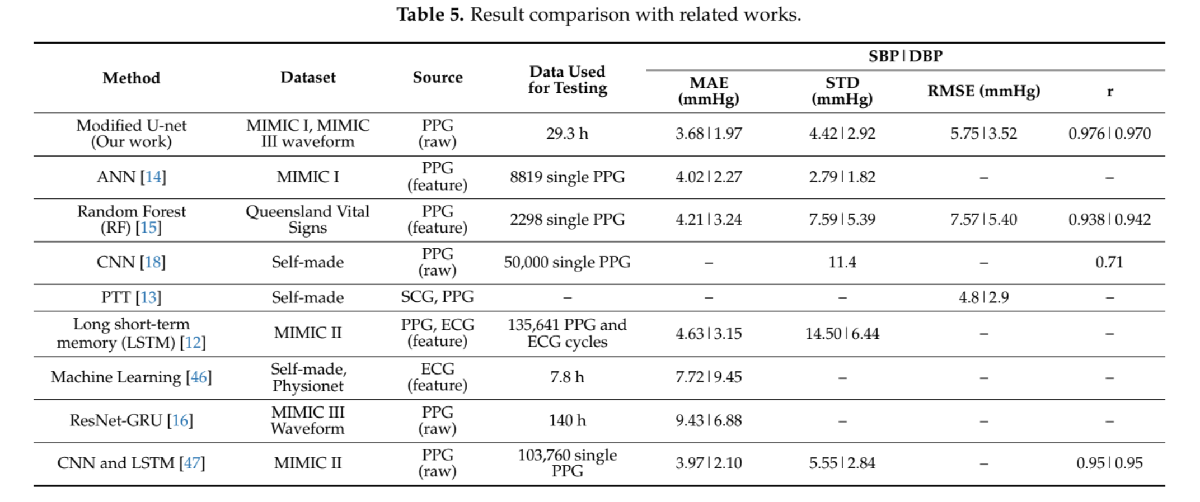

source: T. Athaya, S. Choi "An Estimation Method of Continuous Non-Invasive Arterial Blood Pressure Waveform Using Photoplethysmography: A U-Net Architecture-Based Approach" p. 13


nn4_512m =  fitrnet(trainInputT', trainOutputT', 'Standardize', true, 'LayerSizes',[512,512,512,512,512], 'Verbose',1,'VerboseFrequency',5)  


actualTrainMAP = trainOutputT'*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTrainMAP = predict(dN6, trainInputT')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
trainingError = mean(abs(predictedTrainMAP-actualTrainMAP))
actualTestMAP = testOutputT'*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestMAP = predict(dN6, testInputT')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingError = mean(abs(predictedTestMAP-actualTestMAP))

% load('dnn512_4.mat');
actualTestMAP = outputFeats'*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestMAP = predict(dN5, inputFeats)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingError = (predictedTestMAP-actualTestMAP');
mean(abs(testingError));
clf
scatter(actualTestMAP, testingError,'.')
xlabel("MAP (mmHg)")
ylabel("MAE (mmHg)")
grid on

addSubPaths();
opts = readOptionsStruct();
load('NormalisationFactors.mat')
fileList = dir(opts.segmented_file_dir+"*.txt");
numFiles = length(fileList);

inputFeats = zeros(100000,1250);
outputFeats = zeros(100000,3);

segLength = 10;
segOverlap = 0.2; %proportion that the interpolated points are allowed to overlap in the same segment 

numIndices = 0;
for idx=1:numFiles
    fprintf("\b\b\b\b\b\b%6i", idx);

    dataFile = fopen(opts.segmented_file_dir + fileList(idx).name);
    if(dataFile == -1)
        inputFeatures = [];
        fprintf("%s not found. Returning from function.", opts.segmented_file_dir+segmentName)
        continue; 
    end
    data = cell2mat(textscan( dataFile, ...
    '%f %f %f', 'TreatAsEmpty', '-', 'EmptyValue', 0));
    fclose(dataFile);

    time = data(:,1);
    abp_wave = data(:,2);
    ppg_wave = data(:,3);

    numAvailableSegs = floor(time(end)/segLength*(1+segOverlap));
    
%     outputFeats=outputFeats;
    
    for i = 1:numAvailableSegs
        startInterp = 10*(i-1)*(1-segOverlap);
        if(i == 1); startInterp = 0; end;
        endInterp = startInterp +10;
        interp_pts_ppg = linspace(startInterp,endInterp,1250);
        interp_pts_abp = linspace(endInterp-1,endInterp,125);

        interp_ppg = interp1(time, ppg_wave, interp_pts_ppg);
        interp_ppg = (interp_ppg-normFactors('PPGAmpMean'))./normFactors('PPGAmpScale');
        interp_abp = interp1(time, abp_wave, interp_pts_abp);
        interp_abp = (interp_abp-normFactors('ABPAmpMean'))./normFactors('ABPAmpScale');
        
        if(~isempty(find(isnan(interp_ppg))) && ~isempty(find(isnan(interp_abp)))); continue; end;
        inputFeats(numIndices+1, :) = interp_ppg;
        [sys, dias, meanSBP, meanDBP, MAP] = findABPPeaks(interp_abp,125,false,false);
        if(isempty(sys) || isempty(dias)); continue; end;
        numIndices = numIndices+1;
        outputFeats(numIndices, :) = [meanSBP, meanDBP, MAP];
    end

end

  1818



inputFeats(numIndices:end, :) = [];
outputFeats(numIndices:end, :)=[];

partition_variable = cvpartition(height(inputFeats), "Holdout",0.30);
trainingIndices = training(partition_variable);
trainInputT = inputFeats(trainingIndices,:);
trainOutputT = outputFeats(trainingIndices,:);

nonTrainIndices = test(partition_variable);
validation_partition = cvpartition(length(nonTrainIndices), "Holdout", 0.5);
testIndices = nonTrainIndices(training(validation_partition));
testInputT = inputFeats(testIndices,:);
testOutputT = outputFeats(testIndices,:);
validIndices = nonTrainIndices(test(validation_partition));
validInputT = inputFeats(testIndices,:);
validOutputT = outputFeats(testIndices,:);




% layers = [ ...
%     sequenceInputLayer(1250)
%     batchNormalizationLayer
%     fullyConnectedLayer(1024)
%     reluLayer
%     batchNormalizationLayer
%     fullyConnectedLayer(1024)
%     reluLayer
%     batchNormalizationLayer
%     fullyConnectedLayer(1024)
%     reluLayer
%     batchNormalizationLayer
%     fullyConnectedLayer(1024)
%     reluLayer
%     fullyConnectedLayer(1024)
%     reluLayer
%     batchNormalizationLayer
%     fullyConnectedLayer(2)
%     regressionLayer];
% 
% layers = [ ...
%     featureInputLayer(1250)
%     bilstmLayer(128, 'OutputMode', 'sequence')
%     batchNormalizationLayer
%     lstmLayer(128, 'OutputMode', 'sequence')
%     reluLayer
%     fullyConnectedLayer(512)
%     reluLayer
%     fullyConnectedLayer(1)
%     reluLayer];

% layers = [...
%     sequenceInputLayer(1250)
%     bilstmLayer(128, 'OutputMode', 'sequence')
%     batchNormalizationLayer
%     lstmLayer(128, 'OutputMode', 'sequence')
%     batchNormalizationLayer
%     lstmLayer(128, 'OutputMode', 'sequence')
%     batchNormalizationLayer
%     fullyConnectedLayer(1)
%     reluLayer
%     regressionLayer]

layers = [ ...
    featureInputLayer(1250)
    fullyConnectedLayer(1550)
    reluLayer
    fullyConnectedLayer(1550)
    reluLayer
    fullyConnectedLayer(1550)
    reluLayer
    fullyConnectedLayer(1550)
    reluLayer
    fullyConnectedLayer(3)
    regressionLayer];


options = trainingOptions('adam',...
    'ExecutionEnvironment', 'gpu',...
    'ValidationData', {testInputT', testOutputT'}, ...
    'MaxEpochs', 1500,...
    'L2Regularization', 1e-4, ...
    'ValidationFrequency', 5,...
    'MiniBatchSize', 500,...
    'InitialLearnRate', 1e-5)

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-06
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 0
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 5
                   MiniBatchSize: 1000
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: {[975×1250 double]  [975×3 double]}
             ValidationFrequency: 5
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
            ExecutionEnvironment: 'cpu'
                      WorkerLoad: []
          


[net1, info] = trainNetwork(trainInputT', trainOutputT', net1.Layers, options); save('testDNN_nightrun', 'net1');

|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |         0.14 |         0.15 |       0.0093 |       0.0112 |      1.0000e-06 |
|       2 |           5 |       00:00:07 |         0.14 |         0.15 |       0.0092 |       0.0111 |      1.0000e-06 |
|       3 |          10 |       00:00:14 |         0.14 |         0.15 |       0.0104 |       0.0111 |      1.0000e-06 |
|       4 |          15 |       00:00:20 |         0.14 |         0.15 |       0.0102 |       0.0111 |      1.0000e-06 |
|       5 |          20 |       

net1 =   SeriesNetwork with properties:

         Layers: [11×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'regressionoutput'}


info = struct with fields:
              TrainingLoss: [0.0093 0.0105 0.0104 0.0102 0.0092 0.0104 0.0103 0.0101 0.0092 0.0104 0.0102 0.0100 0.0092 0.0103 0.0102 0.0100 0.0091 0.0103 0.0101 0.0100]
              TrainingRMSE: [0.1365 0.1450 0.1440 0.1431 0.1357 0.1441 0.1437 0.1423 0.1357 0.1443 0.1431 0.1417 0.1356 0.1435 0.1428 0.1416 0.1352 0.1434 0.1424 0.1414]
            ValidationLoss: [0.0112 NaN NaN NaN 0.0111 NaN NaN NaN NaN 0.0111 NaN NaN NaN NaN 0.0111 NaN NaN NaN NaN 0.0110]
            ValidationRMSE: [0.1495 NaN NaN NaN 0.1490 NaN NaN NaN NaN 0.1490 NaN NaN NaN NaN 0.1489 NaN NaN NaN NaN 0.1483]
             BaseLearnRate: [1.0000e-06 1.0000e-06 1.0000e-06 1.0000e-06 1.0000e-06 1.0000e-06 1.0000e-06 1.0000e-06 1.0000e-06 1.0000e-06 1.0000e-06 1.0000e-06 1.0000e-06 1.0000e-06 1.0000e-06 1.0000e-06 1.0000e-06 1.0000e-06 1.0000e-06 1.0000e-06]
       FinalValidationLoss: 0.0110
       FinalValidationRMSE: 0.1483
    OutputNetworkIteration: 20




% nn4_512m =  fitrnet(trainInputT, trainOutputT(:,3), 'Standardize', true, 'LayerSizes',[512,512,512,512], 'Verbose',1,'VerboseFrequency',5)  
% 
% 
% nn5_512s =  fitrnet(trainInputT', trainOutputT(1,:)', 'Standardize', true,...
%     'LayerSizes',[512,512,512,512,512], 'Verbose',1,'VerboseFrequency',5,...
%     'IterationLimit',2e3, 'ValidationData', {validInputT', validOutputT(1,:)'})  
% % 
% % 
% nn3_1024s =  fitrnet(trainInputT, trainOutputT(:,1), 'Standardize', true, 'LayerSizes',[1024,1024,1024], 'Verbose',1,'VerboseFrequency',5)  




n=1;
actualTrainMAP = trainOutputT(n,:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTrainMAP = predict(net1, trainInputT')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
trainingError = (predictedTrainMAP(:,n)-actualTrainMAP');
mean(abs(trainingError))

ans = single
3.0467

sum(abs(trainingError)<10)/length(trainingError)

ans = 0.9633


n=3
actualTestMAP = testOutputT(n,:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestMAP = predict(net1, testInputT)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingError = (predictedTestMAP(:,n)-actualTestMAP');
mean(abs(testingError))

ans = single
3.8919

sum(abs(testingError)<10)/length(testingError)

ans = 0.9335

fitlm(actualTestMAP, predictedTestMAP(:,n))


% 
% clf
% scatter(actualTestMAP, testingError,'.')
% xlabel("MAP (mmHg)")
% ylabel("MAE (mmHg)")
% grid on

% nn

actualTestSBP = testOutputT(:,1)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');

predictedTestVals = predict(net1, testInputT)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean')

predictedTestVals = 977×3 single matrix
  141.6868   73.1291   96.9831
  143.6987   73.1215   97.3457
  142.0318   71.5986   96.3838
  142.8706   72.3194   96.9476
  141.9903   71.2243   95.6903
  141.7363   73.0146   96.6298
  143.7596   72.9352   97.2908
  142.4828   72.4470   96.6940
  142.1115   72.6089   96.7723
  142.9499   72.4189   96.9142



sbp_est = 3.*predictedTestVals(:,3)-2.*predictedTestVals(:,2)

sbp_est = 977×1 single column vector
  144.6909
  145.7943
  145.9541
  146.2040
  144.6224
  143.8602
  146.0021
  145.1879
  145.0991
  145.9046



mean(abs(sbp_est - actualTestSBP))

ans = single
10.0798

sum(abs(sbp_est-actualTestSBP)<10)/length(sbp_est)

ans = 0.5865



lgraph = layerGraph();
tempLayers = sequenceInputLayer(1250,"Name","sequence");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    convolution1dLayer(3,1250,"Name","conv1d_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2")
    convolution1dLayer(3,1250,"Name","conv1d_2","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","addition_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    batchNormalizationLayer("Name","batchnorm_3")
    reluLayer("Name","relu_3")
    convolution1dLayer(3,1250,"Name","conv1d_3","Padding","same")
    batchNormalizationLayer("Name","batchnorm_4")
    reluLayer("Name","relu_4")
    convolution1dLayer(3,1250,"Name","conv1d_4","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_2")
    fullyConnectedLayer(1,"Name","fc")
    regressionLayer("Name","regressionoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

lgraph = connectLayers(lgraph,"sequence","batchnorm_1");
lgraph = connectLayers(lgraph,"sequence","addition_1/in2");
lgraph = connectLayers(lgraph,"conv1d_2","addition_1/in1");
lgraph = connectLayers(lgraph,"addition_1","batchnorm_3");
lgraph = connectLayers(lgraph,"addition_1","addition_2/in2");
lgraph = connectLayers(lgraph,"conv1d_4","addition_2/in1");
plot(lgraph);

options = trainingOptions('adam',...
    'initialLearnRate',0.001,...
    'miniBatchSize', 1024,...
    'ExecutionEnvironment', 'cpu',...
    'ValidationData', {testInputT', testOutputT(:,1)'}, ...
    'MaxEpochs', 150,...
    'L2Regularization', 1e-4, ...
    'ValidationFrequency', 10)

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 150
                   MiniBatchSize: 32
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: {[1250×975 double]  [0.0362 0.1943 0.2746 -0.1254 -0.0922 0.0136 -0.0297 -0.0514 -0.0768 -0.1014 -0.1183 -0.1184 -0.1190 -0.1538 -0.0419 0.0845 0.0824 0.0863 -0.1585 -0.1834 -0.1626 -0.1406 -0.1269 -0.0624 -0.0280 … ]}
             ValidationFrequency: 10
          


[net1, info] = trainNetwork(trainInputT', trainOutputT(:,1)', lgraph, options)

|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |         1.31 |       131.88 |       0.8539 |    8695.6572 |          0.0010 |
|      10 |          10 |       00:00:33 |        42.67 |        45.59 |     910.2108 |    1039.0339 |          0.0010 |
|      20 |          20 |       00:01:05 |        18.81 |        17.83 |     176.9078 |     158.9161 |          0.0010 |
|      30 |          30 |       00:01:42 |        11.72 |         9.51 |      68.6473 |      45.2534 |          0.0010 |
|      40 |          40 |       

net1 =   DAGNetwork with properties:

         Layers: [17×1 nnet.cnn.layer.Layer]
    Connections: [18×2 table]
     InputNames: {'sequence'}
    OutputNames: {'regressionoutput'}


info = struct with fields:
              TrainingLoss: [0.8539 8.6552e+03 570.0748 2.6104e+03 2.9703e+03 1.6150e+03 491.7362 146.1958 485.8831 910.2108 973.7999 695.7820 351.6597 187.5314 207.0840 267.8114 289.6032 259.8833 211.1339 176.9078 162.7363 151.1103 123.7740 91.6277 … ]
              TrainingRMSE: [1.3069 131.5692 33.7661 72.2555 77.0753 56.8330 31.3604 17.0995 31.1732 42.6664 44.1316 37.3037 26.5202 19.3665 20.3511 23.1435 24.0667 22.7984 20.5492 18.8100 18.0409 17.3845 15.7337 13.5372 11.4873 10.9772 12.1391 … ]
            ValidationLoss: [8.6957e+03 NaN NaN NaN NaN NaN NaN NaN NaN 1.0390e+03 NaN NaN NaN NaN NaN NaN NaN NaN NaN 158.9161 NaN NaN NaN NaN NaN NaN NaN NaN NaN 45.2534 NaN NaN NaN NaN NaN NaN NaN NaN NaN 6.1471 NaN NaN NaN NaN NaN NaN NaN NaN NaN … ]
            ValidationRMSE: [131.8761 NaN NaN NaN NaN NaN NaN NaN NaN 45.5858 NaN NaN NaN NaN NaN NaN NaN NaN NaN 17.8278 NaN NaN NaN NaN NaN NaN NaN NaN NaN 9.5135 NaN NaN NaN NaN NaN NaN NaN NaN NaN 3.5063 NaN NaN

actualTrainMAP = trainOutputT(1,:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTrainMAP = predict(net1, trainInputT')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
trainingError = (predictedTrainMAP'-actualTrainMAP);
mean(abs(trainingError))

ans = single
19.9131

sum(abs(trainingError)<10)/length(trainingError)

ans = 0.4066


actualTestMAP = testOutputT(1,:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestMAP = predict(net1, testInputT')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingError = (predictedTestMAP'-actualTestMAP);
mean(abs(testingError))

ans = single
22.9724

sum(abs(testingError)<10)/length(testingError)

ans = 0.3651

##  RESNET

lgraph = resnet18('Weights','none');

tempLayers = [regressionLayer("Name","regression_output")];
lgraph = replaceLayer(lgraph, 'ClassificationLayer_predictions', tempLayers);
tempLayers = [reluLayer("Name","relu_output")];
lgraph = replaceLayer(lgraph, 'ClassificationLayer_predictions', tempLayers);
% lgraph = removeLayers(lgraph, 'prob');

lgraph = connectLayers(lgraph, 'fc1000', 'relu_output')
lgraph = connectLayers(lgraph, 'relu_output', 'regression_output')
lgraph.Layers




options = trainingOptions('adam',...
    'initialLearnRate',0.001,...
    'miniBatchSize', 32,...
    'ExecutionEnvironment', 'gpu',...
    'ValidationData', {testInputT', testOutputT(:,1)'}, ...
    'MaxEpochs', 150,...
    'L2Regularization', 1e-4, ...
    'ValidationFrequency', 10)

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 150
                   MiniBatchSize: 32
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: {[1250×975 double]  [0.5808 0.7647 0.8513 0.3187 0.3731 0.4559 0.4514 0.4349 0.4015 0.3578 0.3350 0.3302 0.3328 0.2730 0.5493 0.4469 0.4469 0.4469 0.3018 0.2674 0.3039 0.3388 0.3570 0.4434 0.4469 0.4458 0.4469 … ]}
             ValidationFrequency: 10
              

Error using trainNetwork (line 184)
Invalid network.

Caused by:
    Network: Disconnected layers. All layers in the layer graph must be connected.
    Detected disconnected layers:
        layer 'regressionoutput'
    Layer 'fc1000': Unconnected output. Each layer output must be connected to the input of another layer.

[net1, info] = trainNetwork(trainInputT', trainOutputT(:,1)', lgraph, options)


tHist = [ 1.4070,  0.0270,  0.0257,  0.0281,  0.0273,  0.0247,  0.0253,  0.0239,  0.0248,  0.0252,  0.0243,  0.0244,  0.0233,  0.0242,  0.0236,  0.0222,  0.0220,  0.0232,  0.0230,  0.0224,  0.0234,  0.0216,  0.0224,  0.0222,  0.0217,  0.0212,  0.0206,  0.0210,  0.0211,  0.0216,  0.0201,  0.0202,  0.0205,  0.0209,  0.0214,  0.0188,  0.0195,  0.0203,  0.0220,  0.0193,  0.0196,  0.0185,  0.0196,  0.0218,  0.0194,  0.0194,  0.0179,  0.0182,  0.0189,  0.0196,  0.0185,  0.0181,  0.0184,  0.0185,  0.0196,  0.0176,  0.0183,  0.0178,  0.0179,  0.0187,  0.0199,  0.0184,  0.0181,  0.0179,  0.0178,  0.0186,  0.0172,  0.0178,  0.0170,  0.0170,  0.0180,  0.0173,  0.0177,  0.0166,  0.0171,  0.0170,  0.0164,  0.0166,  0.0169,  0.0168,  0.0176,  0.0169,  0.0161,  0.0163,  0.0167,  0.0175,  0.0167,  0.0161,  0.0169,  0.0169,  0.0169,  0.0164,  0.0166,  0.0158,  0.0160,  0.0166,  0.0161,  0.0162,  0.0156,  0.0157,  0.0156,  0.0165,  0.0162,  0.0170,  0.0159,  0.0151,  0.0169,  0.0156,  0.0151,  0.0150,  0.0154,  0.0152,  0.0153,  0.0151,  0.0157,  0.0166,  0.0149,  0.0158,  0.0150,  0.0161,  0.0153,  0.0148,  0.0150,  0.0166,  0.0151,  0.0158,  0.0154,  0.0146,  0.0157,  0.0152,  0.0157,  0.0154,  0.0153,  0.0145,  0.0148,  0.0142,  0.0142,  0.0151,  0.0141,  0.0143,  0.0140,  0.0148,  0.0141,  0.0137,  0.0141,  0.0138,  0.0144,  0.0145,  0.0138,  0.0143,  0.0143,  0.0141,  0.0141,  0.0137,  0.0139,  0.0148,  0.0138,  0.0137,  0.0140,  0.0138,  0.0136,  0.0138,  0.0141,  0.0135,  0.0136,  0.0137,  0.0142,  0.0138,  0.0133,  0.0134,  0.0138,  0.0135,  0.0133,  0.0132,  0.0139,  0.0127,  0.0136,  0.0129,  0.0135,  0.0129,  0.0133,  0.0137,  0.0133,  0.0125,  0.0129,  0.0133,  0.0132,  0.0135,  0.0128,  0.0132,  0.0125,  0.0126,  0.0129,  0.0129,  0.0127,  0.0126,  0.0121,  0.0124,  0.0141,  0.0132,  0.0135,  0.0123,  0.0135,  0.0128,  0.0120,  0.0124,  0.0121,  0.0124,  0.0138,  0.0129,  0.0123,  0.0126,  0.0124,  0.0125,  0.0125,  0.0126,  0.0123,  0.0120,  0.0125,  0.0127,  0.0120,  0.0122,  0.0125,  0.0121,  0.0119,  0.0127,  0.0120,  0.0119,  0.0119,  0.0116,  0.0119,  0.0126,  0.0128,  0.0118,  0.0118,  0.0118,  0.0124,  0.0125,  0.0119,  0.0115,  0.0126,  0.0121,  0.0119,  0.0124,  0.0117,  0.0116,  0.0119,  0.0121,  0.0119,  0.0117,  0.0122,  0.0114,  0.0125,  0.0118,  0.0118,  0.0113,  0.0115,  0.0121,  0.0125,  0.0113,  0.0116,  0.0116,  0.0122,  0.0122,  0.0117,  0.0122,  0.0114,  0.0116,  0.0122,  0.0123,  0.0115,  0.0117,  0.0120,  0.0121,  0.0121,  0.0113,  0.0114,  0.0117,  0.0114,  0.0115,  0.0127,  0.0111,  0.0112,  0.0116,  0.0127,  0.0115,  0.0118,  0.0118,  0.0116,  0.0113,  0.0122,  0.0116,  0.0112,  0.0119,  0.0110,  0.0114,  0.0115,  0.0118,  0.0117,  0.0113,  0.0112,  0.0119,  0.0117,  0.0110,  0.0116,  0.0111,  0.0120,  0.0124,  0.0115,  0.0112,  0.0112,  0.0118,  0.0122,  0.0115,  0.0115,  0.0113,  0.0109,  0.0112,  0.0113,  0.0111,  0.0111,  0.0117,  0.0113,  0.0123,  0.0112,  0.0112,  0.0113,  0.0108,  0.0114,  0.0110,  0.0112,  0.0122,  0.0109,  0.0111,  0.0103,  0.0119,  0.0118,  0.0111,  0.0108,  0.0115,  0.0115,  0.0114,  0.0111,  0.0108,  0.0110,  0.0106,  0.0107,  0.0111,  0.0102,  0.0106,  0.0107,  0.0113,  0.0113,  0.0111,  0.0108,  0.0107,  0.0114,  0.0114,  0.0114,  0.0115,  0.0109,  0.0109,  0.0106,  0.0108,  0.0115,  0.0108,  0.0109,  0.0110,  0.0114,  0.0115,  0.0106,  0.0108,  0.0112,  0.0109,  0.0107,  0.0106,  0.0107,  0.0106,  0.0105,  0.0111,  0.0109,  0.0105,  0.0110,  0.0103,  0.0109,  0.0109,  0.0109,  0.0101,  0.0105,  0.0104,  0.0107,  0.0109,  0.0110,  0.0109,  0.0101,  0.0104,  0.0105,  0.0115,  0.0104,  0.0106,  0.0111,  0.0114,  0.0112,  0.0108,  0.0112,  0.0108,  0.0111,  0.0117,  0.0113,  0.0107,  0.0108,  0.0112,  0.0105,  0.0110,  0.0105,  0.0106,  0.0111,  0.0105,  0.0113,  0.0115,  0.0109,  0.0107,  0.0102,  0.0106,  0.0118,  0.0110,  0.0106,  0.0102,  0.0110,  0.0114,  0.0105,  0.0103,  0.0102,  0.0109,  0.0116,  0.0104,  0.0101,  0.0111,  0.0101,  0.0105,  0.0111,  0.0102,  0.0103,  0.0102,  0.0106,  0.0107,  0.0108,  0.0105,  0.0101,  0.0104,  0.0106,  0.0108,  0.0107,  0.0103,  0.0108,  0.0101,  0.0108,  0.0105,  0.0100,  0.0108,  0.0106,  0.0104,  0.0107,  0.0122,  0.0104,  0.0108,  0.0103,  0.0102,  0.0107,  0.0101,  0.0104,  0.0102,  0.0106,  0.0109,  0.0103,  0.0101,  0.0106,  0.0107,  0.0111,  0.0106,  0.0102,  0.0105,  0.0111,  0.0111,  0.0109,  0.0111,  0.0106,  0.0105,  0.0106,  0.0105,  0.0105,  0.0106,  0.0106,  0.0100,  0.0098,  0.0105,  0.0105,  0.0103,  0.0099,  0.0100,  0.0101,  0.0098,  0.0104,  0.0105,  0.0102,  0.0104,  0.0101,  0.0105,  0.0103,  0.0108,  0.0104,  0.0103,  0.0108,  0.0099,  0.0100,  0.0101,  0.0105,  0.0106,  0.0100,  0.0100,  0.0104,  0.0107,  0.0093,  0.0103,  0.0103,  0.0106,  0.0100,  0.0103,  0.0099,  0.0115,  0.0100,  0.0103,  0.0105,  0.0099,  0.0108,  0.0105,  0.0104,  0.0102,  0.0100,  0.0103,  0.0095,  0.0097,  0.0096,  0.0113,  0.0107,  0.0102,  0.0103,  0.0105,  0.0103,  0.0098,  0.0103,  0.0102,  0.0104,  0.0103,  0.0103,  0.0104,  0.0097,  0.0100,  0.0105,  0.0112,  0.0103,  0.0104,  0.0102,  0.0102,  0.0109,  0.0102,  0.0102,  0.0101,  0.0106,  0.0100,  0.0106,  0.0098,  0.0103,  0.0103,  0.0107,  0.0104,  0.0103,  0.0099,  0.0100,  0.0114,  0.0100,  0.0099,  0.0103,  0.0103,  0.0107,  0.0100,  0.0107,  0.0092,  0.0100,  0.0101,  0.0092,  0.0103,  0.0092,  0.0098,  0.0095,  0.0101,  0.0103,  0.0098,  0.0097,  0.0101,  0.0103,  0.0100,  0.0095,  0.0094,  0.0101,  0.0097,  0.0099,  0.0105,  0.0098,  0.0095,  0.0097,  0.0099,  0.0107,  0.0102,  0.0096,  0.0093,  0.0101,  0.0100,  0.0100,  0.0094,  0.0096,  0.0098,  0.0099,  0.0100,  0.0099,  0.0095,  0.0094,  0.0094,  0.0096,  0.0099,  0.0091,  0.0101,  0.0097,  0.0105,  0.0102,  0.0098,  0.0093,  0.0096,  0.0099,  0.0103,  0.0101,  0.0092,  0.0099,  0.0099,  0.0099,  0.0103,  0.0098,  0.0096,  0.0095,  0.0099,  0.0098,  0.0100,  0.0099,  0.0091,  0.0102,  0.0101,  0.0112,  0.0109,  0.0101,  0.0106,  0.0105,  0.0099,  0.0104,  0.0102,  0.0104,  0.0103,  0.0099,  0.0099,  0.0102,  0.0104,  0.0099,  0.0096,  0.0105,  0.0102,  0.0097,  0.0100,  0.0105,  0.0104,  0.0102,  0.0103,  0.0098,  0.0098,  0.0097,  0.0104,  0.0102,  0.0097,  0.0097,  0.0094,  0.0095,  0.0090,  0.0103,  0.0096,  0.0095,  0.0096,  0.0094,  0.0099,  0.0101,  0.0096,  0.0098,  0.0096,  0.0099,  0.0101,  0.0097,  0.0092,  0.0097,  0.0099,  0.0100,  0.0106,  0.0094,  0.0093,  0.0096,  0.0105,  0.0093,  0.0098,  0.0091,  0.0092,  0.0092,  0.0101,  0.0091,  0.0097,  0.0100,  0.0099,  0.0098,  0.0097,  0.0103,  0.0094,  0.0096,  0.0092,  0.0100,  0.0099,  0.0102,  0.0100,  0.0093,  0.0099,  0.0103,  0.0109,  0.0097,  0.0090,  0.0106,  0.0108,  0.0098,  0.0094,  0.0092,  0.0095,  0.0104,  0.0103,  0.0092,  0.0092,  0.0106,  0.0098,  0.0099,  0.0094,  0.0098,  0.0095,  0.0088,  0.0100,  0.0100,  0.0097,  0.0092,  0.0088,  0.0089,  0.0093,  0.0097,  0.0089,  0.0091,  0.0090,  0.0098,  0.0095,  0.0084,  0.0094,  0.0086,  0.0089,  0.0092,  0.0097,  0.0088,  0.0082,  0.0088,  0.0094,  0.0097,  0.0086,  0.0085,  0.0086,  0.0095,  0.0100,  0.0092,  0.0082,  0.0089,  0.0093,  0.0099,  0.0096,  0.0083,  0.0085,  0.0087,  0.0098,  0.0097,  0.0094,  0.0085,  0.0090,  0.0095,  0.0092,  0.0091,  0.0087,  0.0088,  0.0083,  0.0090,  0.0088,  0.0090,  0.0085,  0.0094,  0.0099,  0.0090,  0.0088,  0.0098,  0.0098,  0.0092,  0.0089,  0.0093,  0.0088,  0.0084,  0.0090,  0.0086,  0.0086,  0.0082,  0.0085,  0.0083,  0.0090,  0.0084];